**Load the necessary Modules**

mrstModule add incomp ad-core ad-blackoil ad-eor ad-props mrst-gui % load the required mrst modules
mrstModule list % List the loaded modules

Currently active MRST modules
  * mrst-gui
  * ad-props
  * ad-eor
  * ad-blackoil
  * ad-core
  * incomp


**Set Up the Geometry**

H (rock depth) = 0.2m,    Nz (Points of the spatial Grid) = 100

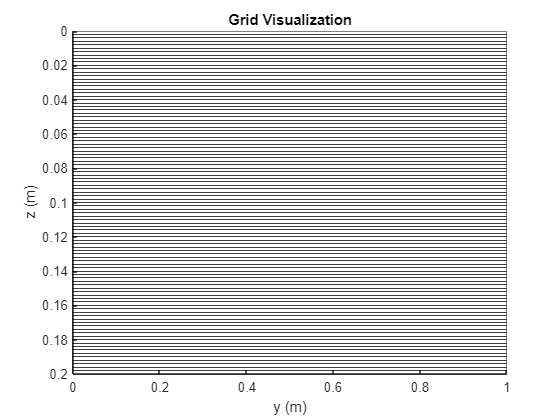

% Step 1: Define the Grid
Nx = 1; % Number of grid cells in the x-direction
Ny = 1; % Number of grid cells in the y-direction
Nz = 100; % Number of grid cells in the z-direction
H = 0.2; % Rock depth (in the z-direction)
Lx = 1; % Length of the domain (in the x-direction)
Ly = 1; % Length of the domain (in the x-direction)
% depth = linspace(0, H, Nz)';
G = cartGrid([Nx, Ny, Nz], [Lx, Ly, H]); % Grid with dimensions [Nx, Ny, Nz] in x-y-z plane

G = computeGeometry(G); % Compute geometry (cell volumes, centroids, face areas, etc.)

% % Plot the grid - 1
plotGrid(G,'FaceColor','none','FaceAlpha',.2,'EdgeAlpha',.5);view([90, 0]); % FaceAlpha, EdgeAlpha(transparency)
xlabel('x (m)');
ylabel('y (m)');
zlabel('z (m)');
title('Grid Visualization');

**Define Rock and Fluid properties**

*Rock Properties:*

$\varphi_0 =0.3$,    $K_0 =0.02\textrm{∙}{10}^{-12} \ m^2$

*Fluid Properties:*

$\mu_w =\mu_o =0.001\ Pa\textrm{∙}s$,    $\rho_w =1000\frac{kg}{m^3 }$,    $\rho_o =660\frac{kg}{m^3 }$,    $k_{rw}^0 =k_{ro}^0 =1$,    $a=b=4$,    $S_{wr} =S_{or} =0.001$

% Step 2: Define Fluid and Rock Properties
perm = repmat(0.02e-12, G.cells.num, 1); % Define initial absolute permeability
poro = 0.3; % Define porosity
rock = makeRock(G,perm,poro); %define intial absolute permeability and porosity
% plotCellData(G,rock.perm); view(3);

fluid = initSimpleADIFluid('phases', 'WO', ...          %Fluid phases: Water, Oil
                           'mu', [0.001, 0.001], ...    %Viscosities [Pa*s]
                           'rho', [1000, 660], ...      %Densities [kg/m^3]
                           'n', [4, 4], ...             %Monomials
                           'smin', [0.001, 0.001]);     %Irreducible Water Saturation and Residual Oil Saturation

*Capillary Pressure:*

$p_c =b_w \textrm{∙}{{\left(S+\varepsilon_1 \right)}}^{-a_w } +b_o \textrm{∙}{{\left(1-S+\varepsilon_2 \right)}}^{-a_o }$,    *N.B. It is defined as an anonymous function of the saturation in the fluid object*

$b_w =500$,    $b_o =-500$,    $a_w =a_o =0.5$

% Define capillary pressure equation parameters
a_w = 0.5; % Pore size distribution index for imbibition
a_o = 0.5; % Pore size distribution index for drainage
b_w = 500; % Constant for entry pressure for imbibition
b_o = -500; % Constant for entry pressure for drainage

% fluid.pcOW = @(s, varargin) b_w.*(max(0, min(1, (s-sl)/(su-sl) )) + eps(10)).^-a_w +b_o.*(1 -max(0, min(1, (s-sl)/(su-sl))) +eps(10)).^-a_o;
% fluid.pcOW = @(s, varargin) b_w.*(s + eps(10)).^-a_w +b_o.*(1 - s +eps(10)).^-a_o;
% fluid.pcOW = @(s, varargin) b_w.*(max(0, min(1, (s - fluid.krPts.w)./(1 - fluid.krPts.o - fluid.krPts.w))) + eps(10)).^-a_w +b_o.*(1 - max(0, min(1, (s - fluid.krPts.w)./(1 - fluid.krPts.o - fluid.krPts.o))) + eps(10)).^-a_o;
fluid.pcOW = @(s, varargin) b_w.*((s - fluid.krPts.w(1))/(1 - fluid.krPts.o(1) - fluid.krPts.o(1)) + eps(10)).^-a_w +b_o.*(1 - (s - fluid.krPts.w(1))/(1 - fluid.krPts.o(1) - fluid.krPts.o(1)) + eps(10)).^-a_o;

disp(fluid);

**Set up the model**

The model object contains the grid, the fluid and rock properties and the modeling equations.

gravity reset on;
model = OilWaterNanoparticlesModel(G,rock,fluid, 'verbose', true);

% Prepare the model for simulation
model = model.validateModel();

% Inspect model
disp(model);

%Inspect state functions
model.setupStateFunctionGroupings();
disp(model.PVTPropertyFunctions);
disp(model.FlowPropertyFunctions);
disp(model.FlowDiscretization);
plotStateFunctionGroupings(model.PVTPropertyFunctions);
plotStateFunctionGroupings(model.FlowPropertyFunctions);
plotStateFunctionGroupings(model.FlowDiscretization);

**Set up Initial and Boundary Conditions**

*Initial Conditions:*

$S_W =S_w^0 \ at\ t=0,\ \ \ \ 0\le z\le H$,    $S_w^0 =0.27$, $S_o^0 =1-S_w^0 =0.73$


$$c=0\ at\ t=0,\ \ \ \ 0\le z\le H$$



$$c_{s1} =c_{s2} =0\ at\ t=0,\ \ \ 0\le z\le H$$


*Boundary Conditions:*


$$S_w =1-S_o^0 ,\ c=c_0 ,\ c_{s1} =c_{s2} =0\ at\ t>0\;\textrm{and}\ z=0,$$
    
$$\left.\left.\left.\left.c_0 =a\right)0.0\frac{m^3 }{m^3 },b\right)\ 0.0009\frac{m^3 }{m^3 },c\right)\ 0.004\frac{m^3 }{m^3 },d\right)\ 0.01\frac{m^3 }{m^3 }$$


                                                                                        
$$S_o^0 =1-S_w^0 =0.73$$


$\frac{dS_w }{dz}=\frac{dc}{dz}=\frac{dc_{s1} }{dz}=\frac{dc_{s2} }{dz}=0\ at\ t>0\;\textrm{and}\;z=H,$    *no-flow boundary condition

% Set up the initial state

% Constant pressure, residual water saturation, no surfactant
% hydrostatic_equilibrium: G.cells.centroids(:,3)*(fluid.rhoWS - fluid.rhoOS)*norm(gravity)
% datum_pressure: 0, atm_pressure: 1*barsa
state0 = initResSol(G, 0, [ 0.27, 0.73]);  % (Ju and Fan, 2009)
state0.cs    = zeros(G.cells.num, 1);
state0.csmax = state0.cs;
state0.cs1   = state0.cs; 
state0.cs2   = state0.cs;

% Prepare state for simulation
state0 = model.validateState(state0);
disp(state0);

% Inspect the fluid properties graphically
% inspectFluidModel(model,'field','Densities');

% Set up boundary conditions
% [Capillary_Pressure] = model.getProp(state0, 'CapillaryPressure'); % Capillary_Pressure{1,1}(1)
% [Capillary_Pressure] = 387.05 % Pa calculated analytically for t=0 (Eq.(12))
% datum_pressure: 0, atm_pressure: 101325 Pa = 1*barsa 

% Dirichlet Boundary Condition at the top
bc = pside([], G, 'zmin', -1.186e+10, 'sat', [1 - fluid.krPts.o(1), fluid.krPts.o(1)]); %% you can use either 'upper', 'zmin'or 'top'
% bc = pside([], G, 'zmin', 1*barsa, 'sat', [1, 0]); %% you can use either 'upper', 'zmin'or 'top'

% % Alternative way to define nanoparticles concentration
% bc.cs = 0.004.*ones(size(bc.sat,1), 1); bc.cs1 = zeros(size(bc.sat,1), 1); bc.cs2 = zeros(size(bc.sat,1), 1);

% % Alternatively, Newmann boundary conditions at the top
% injRate = 1.5e-8; % (Ju and Fan, 2009) OR,
% % pv = poreVolume(G, rock); % Calculated by simple poreVolume function
% % injRate = sum(pv)/(40*day); % Divided by simTime

% Newmann Boundary condition at the bottom
bc = fluxside(bc, G, 'zmax', 0*meter^3/day, 'sat', [0.27, 0.73]); % you can use either 'lower', 'zmax'or 'bottom'

% the cs,cs1,cs2 should only apply to the north/front boundary
bc.cs = [0.004, 0]; 
bc.cs1 = [0,0]; bc.cs2 = [0,0]; % may be redundant

disp(bc);


%plot bc
clf, plotGrid(G,'FaceColor', 'none', 'FaceAlpha',.5,'EdgeAlpha',.5); view(3);
plotFaces(G, bc.face(strcmp(bc.type,'flux')), 'b');
plotFaces(G, bc.face(strcmp(bc.type,'pressure')), 'r');

**Define simulation schedule and set solver parameters**

dt=Adaptive time step

t_inf=2 hr,1 day,10 days,20 days,40 days,80 days

% Schedule: describing time intervals and corresponding drive mechanisms
simTime = 40*day;
% %rumpump time scheduling
% nstep   = 5;
% timesteps = rampupTimesteps(simTime,simTime/(nstep + 1), 5); % ramp up
timesteps = diff(linspace(0,simTime,80)); % linear spacing

schedule = simpleSchedule(timesteps, 'bc', bc);
schedule = model.validateSchedule(schedule);

% Determine the best solver to use for the model
solver = getNonLinearSolver(model);

disp(solver);

**Run and monitor simulation**

% % Perform only 1 iteration
% [dT, n] = deal(40*day, 25);
% states = cell(n+1, 1); states{1} = state0;
% solver.verbose = true;
% for i = 1:n
%     states{i+1} = solver.solveTimestep(states{i}, dT, model, 'bc', bc);
% end
% Setup a function which does some plotting after every timestep
fn = getPlotAfterStep(state0, model, schedule, 'view',[90 0], ...
'plotWell', false, 'plotReservoir', true, 'field', 's:1', 'plot1d', true);
% Run the simulation
mrstVerbose = true;
solver.LinearSolver.verbose = mrstVerbose;
[~, states, report] = simulateScheduleAD(state0, model, schedule, ...
                       'NonLinearSolver', solver, 'afterStepFn',fn, 'verbose', mrstVerbose);
%---------------------------------------------------------------------------------------
% figure()
% plotToolbar(G, statesSurfactant, 'startplayback', true, 'plot1d', true, 'field', 's:1');

**Display Capilllary Pressure Results**

**Eq. (5): **$p_c =p_o -p_w \;\;$

**Eq. (12):** $p_c =b_w \textrm{∙}{{\left(S+\varepsilon_1 \right)}}^{-a_w } +b_o \textrm{∙}{{\left(1-S+\varepsilon_2 \right)}}^{-a_o }$

% model.OutputStateFunctions{end+1} = 'PhasePressures'
% pressure = states.pressure
p_a = model.getProps(states{79,1}, 'PhasePressures');
p_w = cell2mat(p_a(:,1));
p_o = cell2mat(p_a(:,2));
pc_eq5 = p_o - p_w;
pc_eq12 = states{79,1}.FlowProps.CapillaryPressure(:,1);
% pc_eq12 = fluid.pcOW(states{79,1}.s(:,1));
pc ={pc_eq5, pc_eq12};
z = linspace(0, H, Nz);
Z = z./H;
clf; plot(Z,pc{:,1},'r', Z, pc{:,2}, 'bs');
title('Capillary Pressure vs Z');
xlabel ('Z'); ylabel('pc');
% fprintf('pc_eq5 %15.5f pc_eq12 %15.5f\n', pc_eq5, pc_eq12);

**Plotting the results**

- Set  $Z=\frac{z}{H}$

- Plot $c\ vs\ Z$ ; Fig.1

- Plot $S_w \ vs\ Z$ ; Fig.2

- Plot  $\varphi /\varphi_0 \ vs\ Z$ ; Fig.3

- Plot $\frac{K}{K_0 }\ vs\ Z$ ; Fig.4

- Plot $k_{rw} ,\ k_{ro} \ vs\ S$ ; Fig.5

- Plot $p_c \ vs\ S$ ; Fig.6

% Dimensionless Distance
z = linspace(0, H, Nz);
Z = z./H;
% Normalized Water Saturation
S_W = states{79,1}.s(:,1);
S = (S_W - fluid.krPts.w(1))/(1 - fluid.krPts.o(1) - fluid.krPts.o(1));
% Ratio of porosity and permeability
phi = states{79,1}.PVTProps.PoreVolume;
phi_ratio = phi./model.rock.poro;
% K = states{79,1}.PVTProps.AbsolutePermReduction;
% K_ratio = K./model.rock.perm;
% Normalized nanoparticles concentration
c = states{79,1}.cs;
C = c./bc.cs(1);
% RelativePermeabilities and capillary pressure
% kr_O = statesSurfactant{39,1}.PVTProps.PVTBaseRelativePermeability(:,2);
kr_W = states{79,1}.FlowProps.RelativePermeability(:,1);
kr_O = states{79,1}.FlowProps.RelativePermeability(:,2);
pc_OW = states{79,1}.FlowProps.CapillaryPressure(:,1);
%--------------------------------------------------------------------------------------------
figure()
subplot(2,3,1);
plot(Z,C);
title('C vs Z');

subplot(2,3,2);
plot(Z, S_W);
title('S_w vs Z');

subplot(2,3,3);
plot(Z, phi_ratio);
title('phi_ratio vs Z');

% subplot(2,3,4);
% plot(Z, K_ratio);
% title('K_ratio vs Z');

subplot(2,3,5);
plot(S,pc_OW);
title('pc_OW vs S');

subplot (2,3,6);
plot(S, kr_W, 'r-', S, kr_O, 'b-');
title('k_r vs S');